# Create and Customize Area Plots

`area` plots the values of a $Y$ vector input against the *x*-coordinates defined by an $X$ vector input. The function fills the areas between the curve and x-axis. The input $Y$ can also be a matrix containing several datasets in which case an area plot will display the curves stacked on top of each other.

### Create a Random Data Set

Create a 10-by-4 matrix containing four sets of data randomly sampled about the line $y=x$. Specify group names for each set and create a vector `points `to represent the number of elements in each set.

x = (1:1:10);
areaData = [x.* rand(1,10) * 5
            x.* rand(1,10) * 5
            x.* rand(1,10) * 5 
            x.* rand(1,10) * 5]';
groups = {"set 1", "set 2", "set 3", "set 4"};
points = (1:10);

### Basic Area Plot

Plot the data by passing the matrix to the area command.

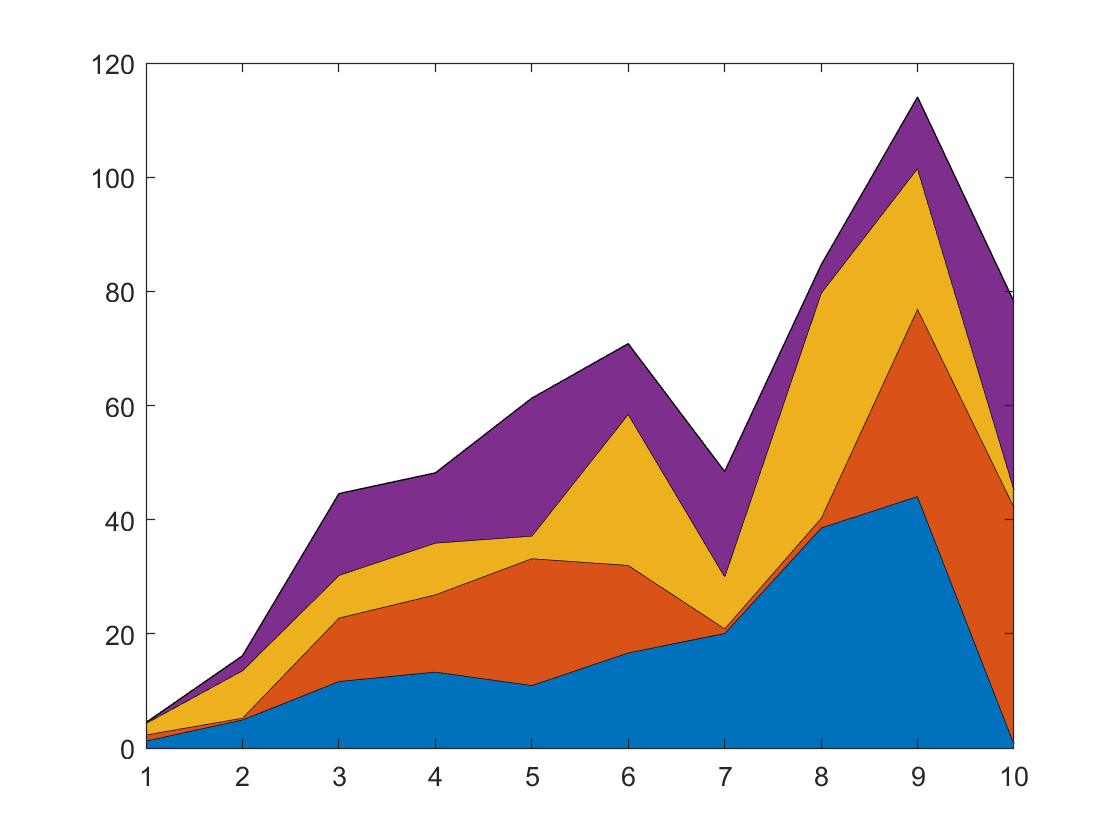

area(areaData);

## Customizations

### Adding a Legend and Axis TItles

Add the vector `points` to define the $x$ axis which corresponds to the rows in the data matrix. Create a legend from a vector defining the groups which correspond to the columns in the data matrix.   

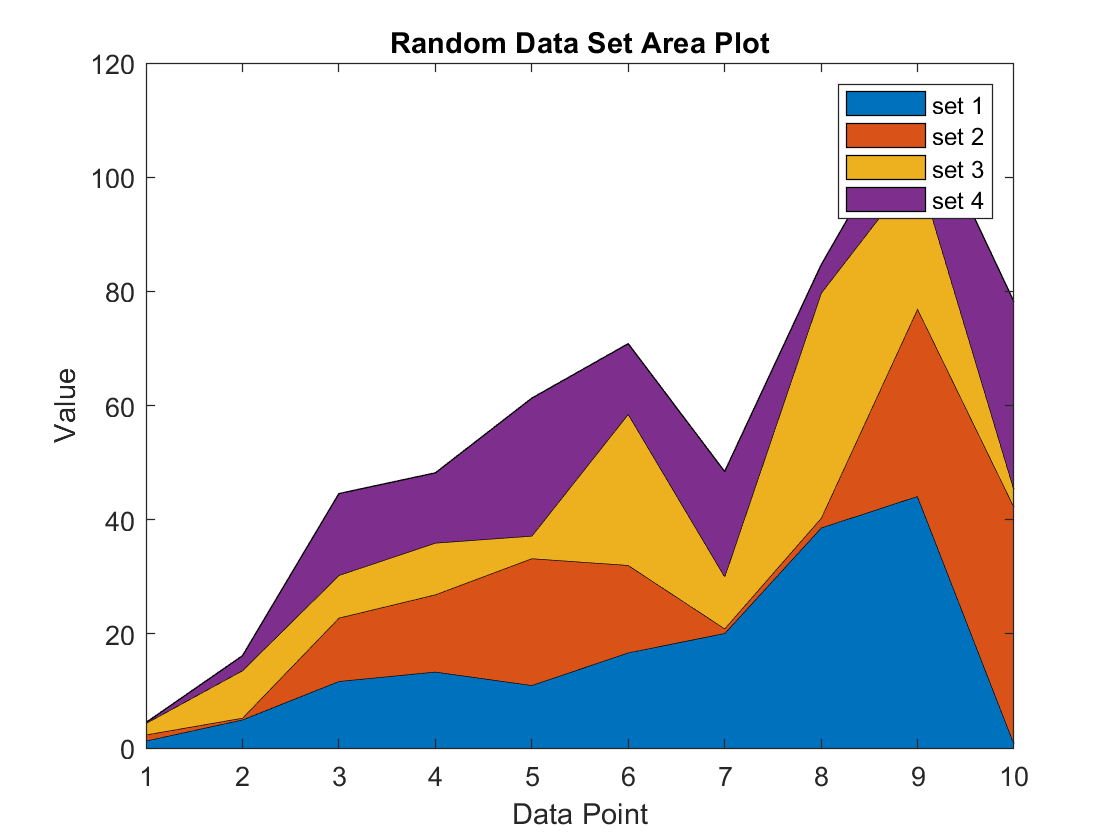

% Add a legend
a = area(points, areaData);
legend(groups)

% Add title and axis labels
title("Random Data Set Area Plot")
xlabel("Data Point")
ylabel("Value")

### Specify Custom Color Pallettes

Custom color palletes can add aesthetic color themes to an area plot. Initialize a colormap with the same dimensions as the data matrix. Use `colororder` to apply the custom color map to the area plot.

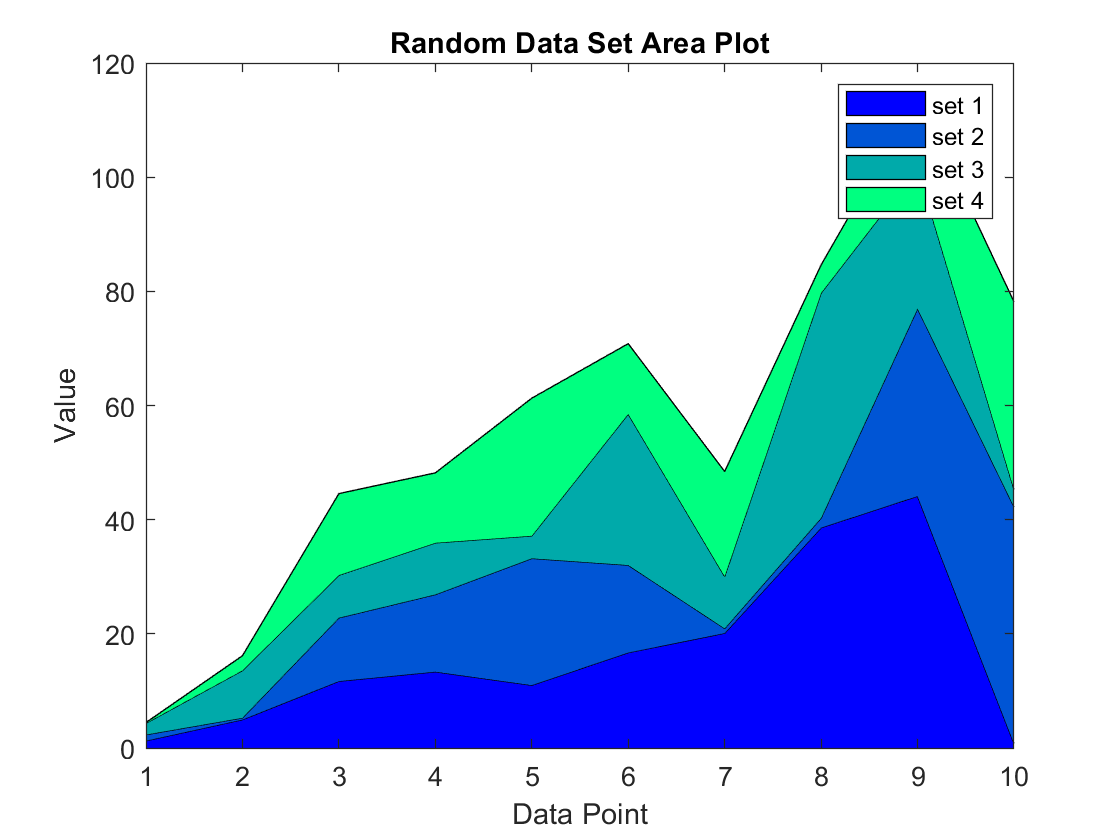

newcolors = winter(size(areaData, 2));           % Initialize a custom colors from the built in winter map 
colororder(newcolors); 

## Additional Information

### Get All Area Properties

Graphics objects in MATLAB have many properties. To see all the properties of an areav plot, uncomment the following code

% get(a(1))

    AlignVertexCenters: off
            Annotation: [1×1 matlab.graphics.eventdata.Annotation]
              BaseLine: [1×1 Baseline]
             BaseValue: 0
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
              Clipping: on
           ContextMenu: [0×0 GraphicsPlaceholder]
             CreateFcn: ''
       DataTipTemplate: [1×1 matlab.graphics.datatip.DataTipTemplate]
             DeleteFcn: ''
           DisplayName: 'set 1'
             EdgeAlpha: 1
             EdgeColor: [0 0 0]
             FaceAlpha: 1
             FaceColor: [0 0 1]
         FaceColorMode: 'auto'
      HandleVisibility: 'on'
               HitTest: on
         Interruptible: on
             LineStyle: '-'
             LineWidth: 0.5000
                Parent: [1×1 Axes]
         PickableParts: 'visible'
              Selected: off
    SelectionHighlight: on
           SeriesIndex: 1
          ShowBaseLine: on
    

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[area](https://www.mathworks.com/help/matlab/ref/area.html)